for table_i=1:50
    n{table_i} = ['Hidden Layer size: ' num2str(table_i,'%d')];
end
name=n';
table_2_lm=array2table([rms_val_lm,r2_val_lm,mape_val_lm],"VariableNames",{'ΔP/ΔPo(rmse)','ΔNu/ΔNuo(rmse)','ΔP/ΔPo(R2)','ΔNu/ΔNuo(R2)','ΔP/ΔPo(mape)','ΔNu/ΔNuo(mape)'});
table_2_lm=cat(2,name,table_2_lm)

table_2_lm = 50×7 table
              Var1               ΔP/ΔPo(rmse)    ΔNu/ΔNuo(rmse)    ΔP/ΔPo(R2)    ΔNu/ΔNuo(R2)    ΔP/ΔPo(mape)    ΔNu/ΔNuo(mape)
    _________________________    ____________    ______________    __________    ____________    ____________    ______________

    {'Hidden Layer size: 1' }       0.33627          0.15126        0.14217       0.00094082        14.369           13.889    
    {'Hidden Layer size: 2' }        0.3286          0.10332        0.18086          0.53386        13.429            8.685    
    {'Hidden Layer size: 3' }        0.1081          0.10039        0.91135          0.55988        6.5402           8.1558    
    {'Hidden Layer size: 4' }       0.13634         0.089535        0.85899          0.64994     


table_2_bay=array2table([rms_val_bay,r2_val_bay,mape_val_bay],"VariableNames",{'ΔP/ΔPo(rmse)','ΔNu/ΔNuo(rmse)','ΔP/ΔPo(R2)','ΔNu/ΔNuo(R2)','ΔP/ΔPo(mape)','ΔNu/ΔNuo(mape)'});
table_2_bay=cat(2,name,table_2_bay)

table_2_bay = 50×7 table
              Var1               ΔP/ΔPo(rmse)    ΔNu/ΔNuo(rmse)    ΔP/ΔPo(R2)    ΔNu/ΔNuo(R2)    ΔP/ΔPo(mape)    ΔNu/ΔNuo(mape)
    _________________________    ____________    ______________    __________    ____________    ____________    ______________

    {'Hidden Layer size: 1' }       0.34707           0.1075        0.086198       0.49535          14.198           9.0918    
    {'Hidden Layer size: 2' }       0.15316          0.10831         0.82204       0.48771          8.5892           9.1003    
    {'Hidden Layer size: 3' }       0.13458          0.10761         0.86261       0.49434          8.0062           9.0538    
    {'Hidden Layer size: 4' }       0.10056         0.094628         0.92329       0.60898      


table_2_scg=array2table([rms_val_scg,r2_val_scg,mape_val_scg],"VariableNames",{'ΔP/ΔPo(rmse)','ΔNu/ΔNuo(rmse)','ΔP/ΔPo(R2)','ΔNu/ΔNuo(R2)','ΔP/ΔPo(mape)','ΔNu/ΔNuo(mape)'});
table_2_scg=cat(2,name,table_2_scg)

table_2_scg = 50×7 table
              Var1               ΔP/ΔPo(rmse)    ΔNu/ΔNuo(rmse)    ΔP/ΔPo(R2)    ΔNu/ΔNuo(R2)    ΔP/ΔPo(mape)    ΔNu/ΔNuo(mape)
    _________________________    ____________    ______________    __________    ____________    ____________    ______________

    {'Hidden Layer size: 1' }       0.34773          0.10702        0.082716       0.49985          14.171           9.0422    
    {'Hidden Layer size: 2' }       0.15524          0.10812         0.81719       0.48955          8.7056           9.0724    
    {'Hidden Layer size: 3' }       0.15009          0.10764         0.82911       0.49406           8.426           9.0113    
    {'Hidden Layer size: 4' }       0.10825          0.10001         0.91111       0.56322      


writetable(table_2_lm,'D:/Matlab Drive/research/Figure/All Algorithm optimization comparison (new)/Performence(validation).xlsx','Sheet','Lavenberg')
writetable(table_2_bay,'D:/Matlab Drive/research/Figure/All Algorithm optimization comparison (new)/Performence(validation).xlsx','Sheet','bayesian')
writetable(table_2_scg,'D:/Matlab Drive/research/Figure/All Algorithm optimization comparison (new)/Performence(validation).xlsx','Sheet','Scg')

table_1=[T_lm_val;T_scg_val;T_bay_val]

table_1 = 6×6 table
           Var1             mae          mse          rmse        Rsq       mape 
    __________________    ________    __________    ________    _______    ______

    {'Pressure_ratio'}    0.015216    0.00048102    0.021932    0.99635    1.3334
    {'Nusselt ratio' }    0.012437    0.00036894    0.019208    0.98389    1.4704
    {'Pressure_ratio'}    0.036617     0.0026434    0.051414    0.97995    3.1823
    {'Nusselt ratio' }    0.026201     0.0013526    0.036777    0.94094    3.0984
    {'Pressure_ratio'}    0.013601    0.00038339     0.01958    0.99709    1.2247
    {'Nusselt ratio' }    0.011275    0.00030884    0.017574    0.98651    1.3346


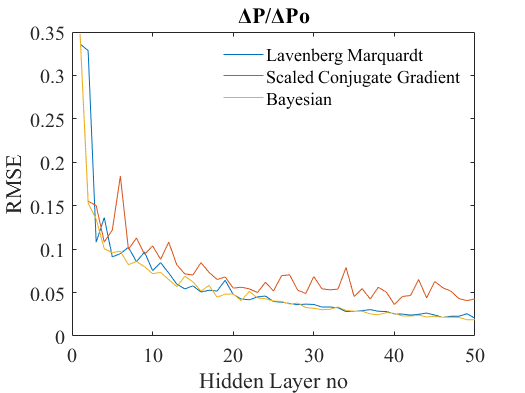

a=figure();
box on;
hold on;
plot(1:50,rms_val_lm(:,1));
plot(1:50,rms_val_scg(:,1));
plot(1:50,rms_val_bay(:,1));
set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',15,...
'FontName','Times')
xlabel('Hidden Layer no')
ylabel('RMSE')
title('ΔP/ΔPo')
legend('Lavenberg Marquardt','Scaled Conjugate Gradient','Bayesian',"Box","off");hold off;
Plot_rmse=sprintf('D:/Matlab Drive/research/Figure/All Algorithm optimization comparison (new)/ΔP÷ΔPo_optimisation(rmse).jpg');
exportgraphics(gcf,Plot_rmse)

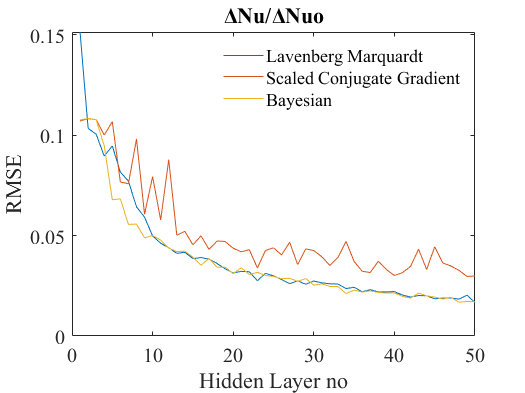


b=figure();
box on;
hold on;
plot(1:50,rms_val_lm(:,2));
plot(1:50,rms_val_scg(:,2));
plot(1:50,rms_val_bay(:,2));
set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',15,...
'FontName','Times')
xlabel('Hidden Layer no')
ylabel('RMSE')
title('ΔNu/ΔNuo')
legend('Lavenberg Marquardt','Scaled Conjugate Gradient','Bayesian',"Box","off");hold off;
Plot_rmse=sprintf('D:/Matlab Drive/research/Figure/All Algorithm optimization comparison (new)/ΔNu÷ΔNuo_optimisation(rmse).jpg');
exportgraphics(gcf,Plot_rmse)

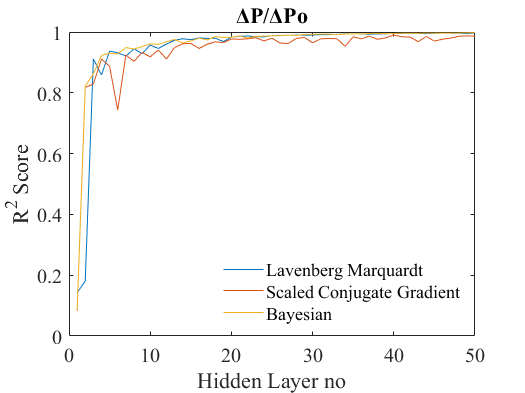

a=figure();
box on;
hold on;
plot(1:50,r2_val_lm(:,1));
plot(1:50,r2_val_scg(:,1));
plot(1:50,r2_val_bay(:,1));
set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',15,...
'FontName','Times')
xlabel('Hidden Layer no')
ylabel('R^2 Score')
title('ΔP/ΔPo')
legend('Lavenberg Marquardt','Scaled Conjugate Gradient','Bayesian','location','southeast',"Box","off");hold off;
Plot_r2=sprintf('D:/Matlab Drive/research/Figure/All Algorithm optimization comparison (new)/ΔP÷ΔPo_optimisation(r2).jpg');
exportgraphics(gcf,Plot_r2)

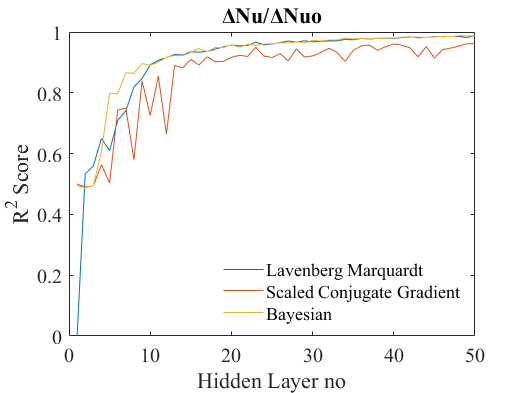


b=figure();
box on;
hold on;
plot(1:50,r2_val_lm(:,2));
plot(1:50,r2_val_scg(:,2));
plot(1:50,r2_val_bay(:,2));
set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',15,...
'FontName','Times')
xlabel('Hidden Layer no')
ylabel('R^2 Score')
title('ΔNu/ΔNuo')
legend('Lavenberg Marquardt','Scaled Conjugate Gradient','Bayesian','location','southeast',"Box","off");hold off;
Plot_r2=sprintf('D:/Matlab Drive/research/Figure/All Algorithm optimization comparison (new)/ΔNu÷ΔNuo_optimisation(r2).jpg');
exportgraphics(gcf,Plot_r2)

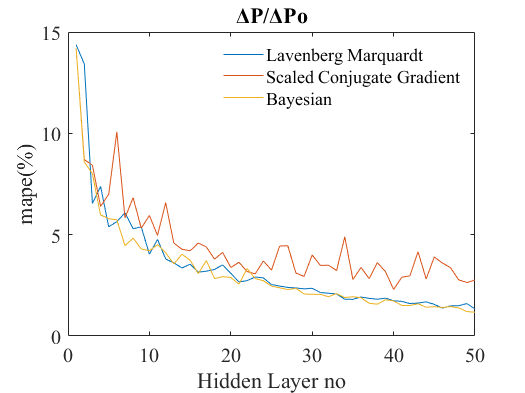

a=figure();
box on;
hold on;
plot(1:50,mape_val_lm(:,1));
plot(1:50,mape_val_scg(:,1));
plot(1:50,mape_val_bay(:,1));
set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',15,...
'FontName','Times')
xlabel('Hidden Layer no')
ylabel('mape(%)')
title('ΔP/ΔPo')
legend('Lavenberg Marquardt','Scaled Conjugate Gradient','Bayesian',"Box","off");hold off;
Plot_mape=sprintf('D:/Matlab Drive/research/Figure/All Algorithm optimization comparison (new)/ΔP÷ΔPo_optimisation(mape).jpg');
exportgraphics(gcf,Plot_mape)

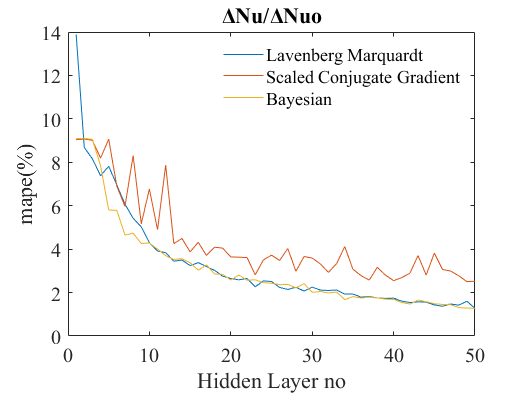


b=figure();
box on;
hold on;
plot(1:50,mape_val_lm(:,2));
plot(1:50,mape_val_scg(:,2));
plot(1:50,mape_val_bay(:,2));
set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',15,...
'FontName','Times')
xlabel('Hidden Layer no')
ylabel('mape(%)')
title('ΔNu/ΔNuo')
legend('Lavenberg Marquardt','Scaled Conjugate Gradient','Bayesian',"Box","off");hold off;
Plot_mape=sprintf('D:/Matlab Drive/research/Figure/All Algorithm optimization comparison (new)/ΔNu÷ΔNuo_optimisation(mape).jpg');
exportgraphics(gcf,Plot_mape)